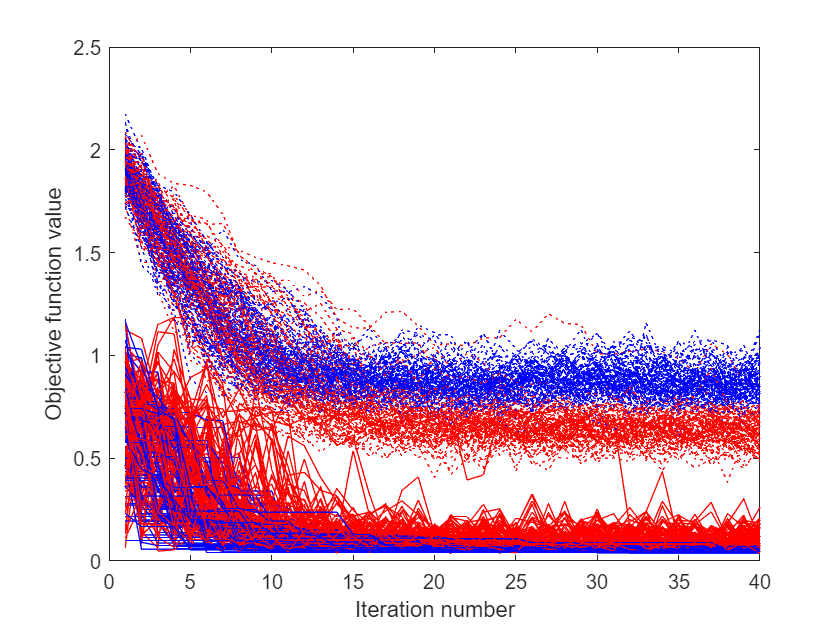

cd functions;
n=100;


[bestresult1,Results1,meanGAmm,stdGAmm,BestHistory1,CurrentHistory1] = GAmm(n);

[bestresult,Results,meanGAes,stdGAes,BestHistory2,CurrentHistory2] = GAesmm(n);

for i=1:n
figure(1);
 plot(BestHistory1(i,:),'Color','r'); hold on      
   plot(CurrentHistory1(i,:),'Color','r','LineStyle',':'); hold on
    plot(BestHistory2(i,:),'Color','b'); hold on      
   plot(CurrentHistory2(i,:),'Color','b','LineStyle',':'); hold on
    xlabel('Iteration number');
    ylabel('Objective function value');
end

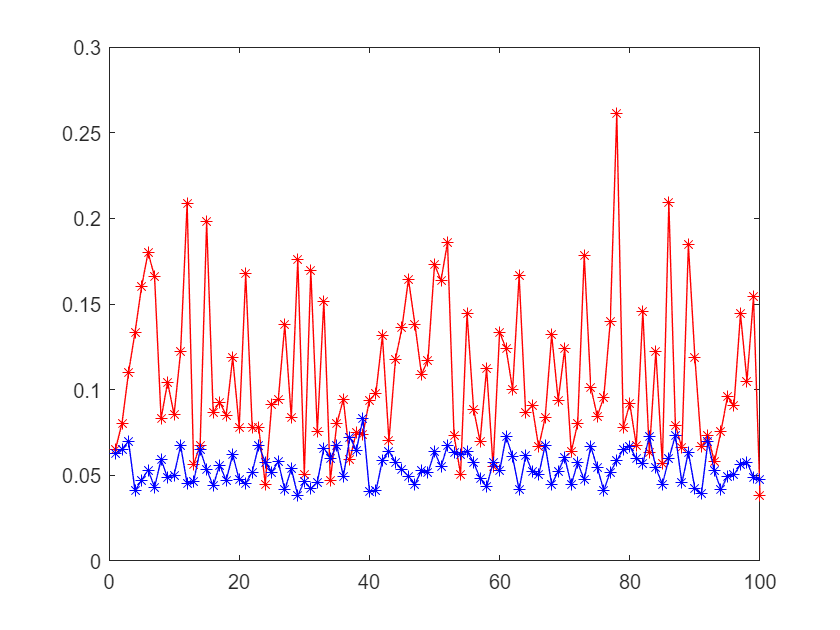


figure(2);
plot(Results1,'r','Marker','*');hold on;
plot(Results,'b','Marker','*');

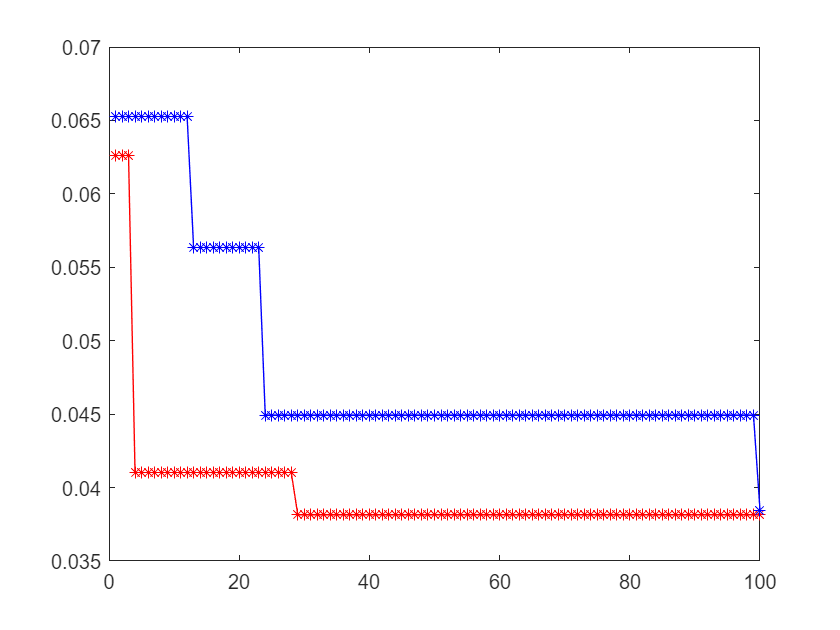


figure(3);
plot(bestresult,'r','Marker','*');hold on;
plot(bestresult1,'b','Marker','*');